clear; close all;
%% 0. Initialize Parameters
L = 1200;
n = 1200;
P = 400;
x = linspace(0, L, n+1);
%% 1. SFD, BMD under train loading
x_train = [52 228 392 568 732 908]; P_train=[1 1 1 1 1 1]*P/6;
n_train = 420;
SFDi = zeros(n_train, n+1);
BMDi = zeros(n_train, n+1);


% Length of bridge
% Discretize into 1 mm seg.
% Total weight of train [N]
% x-axis
% Train Load Locations
% num of train locations
% 1 SFD for each train loc.
% 1 BMD for each train loc.
% Solve for SFD and BMD with the train at different locations
max_sfd = zeros(1, n_train)
max_bmd = zeros(1, n_train)

for i = 1:240
    locations = linspace(0,n,1201);
    loads = zeros(0, 1201);
    x_train = [52 228 392 568 732 908]+i;
    
    r_B = (sum(x_train)*P/6)/1200;
    cumsum(x_train);
    
    r_A = P - r_B;
    
    loads(1) = r_A ;
    loads(1201) = r_B ;
    
    for wheel = 1:length(x_train)
        loads(x_train(wheel)) = -P/6;
    end
    
    for j = 1:length(loads)
        sfd = cumsum(loads);
        bmd = cumsum(sfd*1);
    end  
    max_sfd(1, i) = max(sfd);
    max_bmd(1, i) = max(bmd);
end 

[max_shear, location_max_sfd] = max(max_sfd)
[max_bending, location_max_bmd] = max(max_bmd)


envelope_bmd = zeros(1, 1201);
envelope_sfd = zeros(1, 1201);
   
envelope_bmd 
envelope_sfd


for i = 1:240
    cur_max_bmd = 0;
    cur_max_sfd = 0;
    locations = linspace(0,n,1201);

    loads = zeros(0, 1201);
    x_train = [52 228 392 568 732 908] + i;
    
    r_B = (sum(x_train)*P/6)/1200;
    cumsum(x_train);
    r_A = P - r_B;
    
    loads(1) = r_A ;
    loads(1201) = r_B ;
    
    for wheel = 1:length(x_train)
        loads(x_train(wheel)) = -P/6;
    end
    
    for j = 1:length(loads)
        sfd = cumsum(loads);
        bmd = cumsum(sfd*1);
    end 
    for k = 1:1201
        if bmd(k) > envelope_bmd(1,k)
            envelope_bmd(1,k) = bmd(k);
      
        end

        if abs(sfd(k)) > envelope_sfd(1,k)
            envelope_sfd(1,k) = abs(sfd(k));
        end 
    end
end

%plot(locations, envelope_sfd)
%hold off
%plot(locations, envelope_bmd)





% defining parameters 


x_Tflange = 100;
y_Tflange = 1.27;
y_Bflange = 1.27;
x_Bflange = 80;

x_ledge = 5;
y_ledge = 1.27;
x_web = 1.27;
y_web = 73.73;


Tflange = [x_Tflange, y_Tflange, 75, 1];
ledge = [x_ledge, y_ledge, 73.73, 2];
web = [x_web, y_web, 1.27, 2];
Bflange = [x_Bflange, y_Bflange, 0, 1];

parameters = [Bflange; web; ledge; Tflange]

parameters =    80.0000    1.2700         0    1.0000
    1.2700   73.7300    1.2700    2.0000
    5.0000    1.2700   73.7300    2.0000
  100.0000    1.2700   75.0000    1.0000



height = sum(parameters(:,2)) - 1.27

height = 76.2700

%% local_centroids + areas 
local_centroids = zeros(length(parameters), 1);
local_areas = zeros(length(parameters), 1);
for i = 1:length(parameters)
    local_centroids(i, 1) = parameters(i, 3) + (parameters(i,2)/2);
    local_areas(i, 1) = parameters(i, 1) * parameters(i, 2)*parameters(i,4);
end 
local_centroids

local_centroids =     0.6350
   38.1350
   74.3650
   75.6350


local_areas

local_areas =   101.6000
  187.2742
   12.7000
  127.0000



% centroid 
centroid = dot(local_centroids, local_areas)/sum(local_areas)

centroid = 41.4311



% second moment of area
second_moment_I = dot(parameters(:,1).* parameters(:,4), parameters(:,2).^3)/12 + dot(local_areas, (local_centroids-centroid).^2)

second_moment_I = 4.1835e+05


% first moment of area cent
first_moment_Q_cent = 0

first_moment_Q_cent = 0

for i=1:length(local_centroids)
    if (centroid > parameters(i, 3)) && (centroid > parameters(i, 2)+parameters(i,3))
        first_moment_Q_cent = first_moment_Q_cent + parameters(i, 4)*local_areas(i, 1)*(centroid-local_centroids(i, 1));

    elseif (centroid < parameters(i, 3)+parameters(i, 2)) && (centroid > parameters(i, 3))
        first_moment_Q_cent = first_moment_Q_cent + parameters(i, 4)*(centroid-parameters(i,3))*parameters(i,1)*(centroid-parameters(i,3))/2;
    else
    end
end
first_moment_Q_cent 

first_moment_Q_cent = 6.1933e+03


% first moment of area glue INPUT MANUALLY
first_moment_Q_glue = local_areas(4,1)*parameters(4,4)*(local_centroids(4,1)-centroid)

first_moment_Q_glue = 4.3439e+03


sum(local_areas)

ans = 428.5742

centroid

centroid = 41.4311

second_moment_I

second_moment_I = 4.1835e+05

first_moment_Q_cent

first_moment_Q_cent = 6.1933e+03

first_moment_Q_glue

first_moment_Q_glue = 4.3439e+03

Failure

tensile_strength = 30

tensile_strength = 30

compressive_strength = 6

compressive_strength = 6

shear_strength = 4

shear_strength = 4

young_modulus = 4000

young_modulus = 4000

poisson_r = 0.2

poisson_r = 0.2000

shear_glue = 2

shear_glue = 2

diaphragm = 400

diaphragm = 400

% flexural stresses

sigma_tens = (max_bending*centroid)/second_moment_I % take cent since tens @ bottom 

sigma_tens = 6.8591

 
sigma_comp = (max_bending*(height - centroid)/second_moment_I)

sigma_comp = 5.7677


% shear stresses

tau_cent = (max_shear*first_moment_Q_cent)/(second_moment_I*parameters(2,1)*parameters(2,4)) % looking at thickness of web

tau_cent = 1.3969


tau_glue = (max_shear*first_moment_Q_glue)/(second_moment_I*10) % input the width of glue manually

tau_glue = 0.2489



% thin plate buckling 
c = (pi^2 * young_modulus)/(12*(1-poisson_r^2))

c = 3.4269e+03

ks = [4 0.425 6 5]

ks =     4.0000    0.4250    6.0000    5.0000



% case 1 k = 4
sigma_1 = ks(1, 1) * c * (parameters(4, 2)/(parameters(1,1)-2*parameters(2,1)))^2

sigma_1 = 3.6848


% case 2 k = 0.425
sigma_2 = ks(1, 2) * c * (parameters(4, 2)/(parameters(4,1)-parameters(1,1)))^2

sigma_2 = 5.8728


% case 3 k = 6 
sigma_3 = ks(1, 3) * c * (parameters(2,1)/(parameters(2,2)/2))^2

sigma_3 = 24.4027


% case 4 k = 5
tau_tpb = ks(1, 4) * c * ( (parameters(2,1)/parameters(2,2))^2 +   (parameters(2,1)/diaphragm)^2 )

tau_tpb = 5.2566

capacities

capacities =    30.0000    6.0000    4.0000    2.0000    3.6848    5.8728   24.4027    5.2566



capacities = [tensile_strength, compressive_strength, shear_strength, shear_glue, sigma_1 , sigma_2, sigma_3, tau_tpb]; % maximum capacities

applied = [sigma_tens, sigma_comp, tau_cent, tau_glue, sigma_comp, sigma_comp, sigma_comp, tau_cent]

applied =     6.8591    5.7677    1.3969    0.2489    5.7677    5.7677    5.7677    1.3969



FOS = capacities ./ applied 

FOS =     4.3738    1.0403    2.8636    8.0368    0.6389    1.0182    4.2309    3.7632



min(FOS)

ans = 0.6389

Other Envelopes 

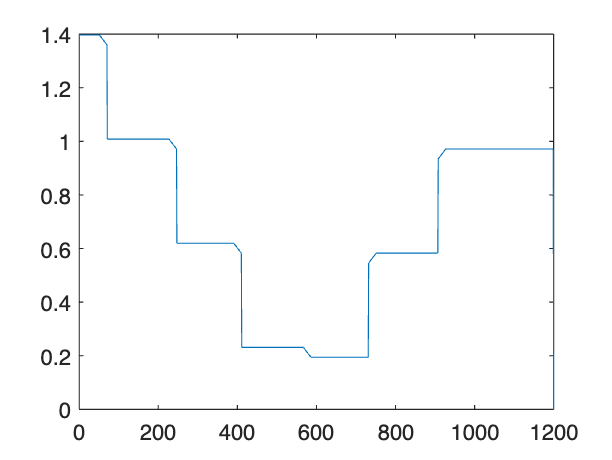

envelope_matboard_shear = zeros(1, 1201);

for i = 1:240
    locations = linspace(0,n,1201);

    loads = zeros(0, 1201);
    x_train = [52 228 392 568 732 908] + i;
    
    r_B = (sum(x_train)*P/6)/1200;
    cumsum(x_train);
    r_A = P - r_B;
    
    loads(1) = r_A ;
    loads(1201) = r_B ;
    
    for wheel = 1:length(x_train)
        loads(x_train(wheel)) = -P/6;
    end
    
    for j = 1:length(loads)
        tau_cent = (envelope_sfd*first_moment_Q_cent)/(second_moment_I*parameters(2,1)*parameters(2,4)); % looking at thickness of web
    end 

    for k = 1:1201
           envelope_matboard_shear(1,k) = tau_cent(k);
        
    end
 
end

plot(locations, envelope_matboard_shear)